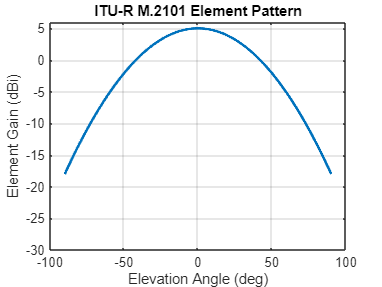

clear
clc

params.theta3dB = 65;
params.phi3dB   = 65;
params.SLAv     = 30;
params.Am       = 30;
params.elementGain = 5;

theta = -90:0.2:90;
phi = 0;

G = elementPattern(theta, phi, params);

figure
plot(theta, G, 'LineWidth',2)
grid on
xlabel('Elevation Angle (deg)')
ylabel('Element Gain (dBi)')
title('ITU-R M.2101 Element Pattern')
ylim([-30 6])

clear
clc

params.M = 16;
params.N = 16;

params.dv = 0.5;
params.dh = 0.5;

params.thetaScan = 45;
params.phiScan = 0;

W = beamWeights(params);

disp(size(W))

    16    16



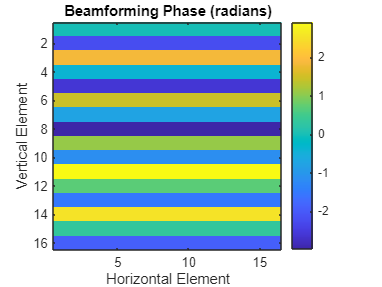


figure
imagesc(angle(W))
colorbar
axis image
xlabel('Horizontal Element')
ylabel('Vertical Element')
title('Beamforming Phase (radians)')

clear
clc

%% Parameters

params.M = 16;
params.N = 16;

params.dv = 0.5;
params.dh = 0.5;

params.thetaScan = 0;
params.phiScan = 0;

%% Beam weights

W = beamWeights(params);

%% Vertical cut

theta = -90:0.2:90;

phi = zeros(size(theta));

AF = arrayFactor(theta,phi,W,params);

AFdB = 20*log10(AF+eps);

AFdB = max(AFdB,-60);

figure

plot(theta,AFdB,'LineWidth',2)

grid on

xlabel('\theta (deg)')

ylabel('Array Factor (dB)')

title('16×16 Planar Array Factor')

ylim([-60 1])

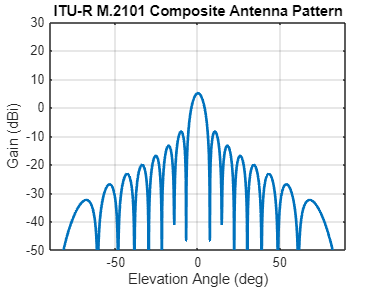

clear
clc

%% Parameters

params.M = 16;
params.N = 16;

params.dv = 0.5;
params.dh = 0.5;

params.elementGain = 5;

params.theta3dB = 65;
params.phi3dB = 65;

params.SLAv = 30;
params.Am = 30;

params.Gmax = 29;

params.thetaScan = 0;
params.phiScan = 0;

%% Vertical Cut

theta = -90:0.2:90;

phi = zeros(size(theta));

Gain = compositeGain(theta, phi, params);

figure

plot(theta, Gain,'LineWidth',2)

grid on

xlabel('Elevation Angle (deg)')

ylabel('Gain (dBi)')

title('ITU-R M.2101 Composite Antenna Pattern')

ylim([-50 30])

xlim([-90 90])

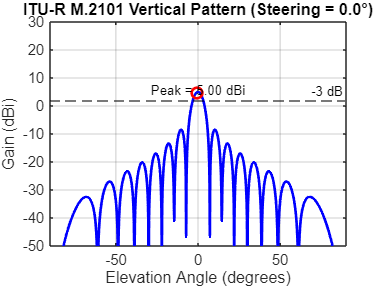


--------------------------------------
Vertical Pattern
Peak Gain        : 5.00 dBi
3 dB Beamwidth   : 6.00 deg
Steering Angle   : 0.00 deg
--------------------------------------


theta = -90:0.2:90;

params.thetaScan = 0;
params.phiScan = 0;

verticalCut(theta,params);

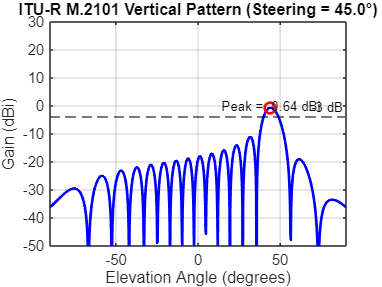


--------------------------------------
Vertical Pattern
Peak Gain        : -0.64 dBi
3 dB Beamwidth   : 8.40 deg
Steering Angle   : 45.00 deg
--------------------------------------


params.thetaScan = 45;

verticalCut(theta,params);

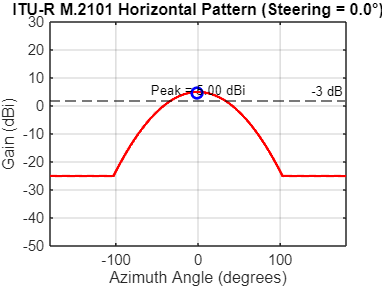


--------------------------------------
Horizontal Pattern
Peak Gain        : 5.00 dBi
3 dB Beamwidth   : 64.80 deg
Steering Azimuth : 0.00 deg
--------------------------------------


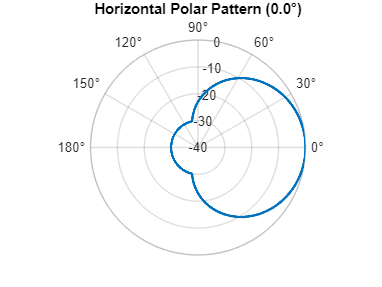

phi = -180:0.2:180;

params.thetaScan = 0;
params.phiScan = 0;

horizontalCut(phi,params);

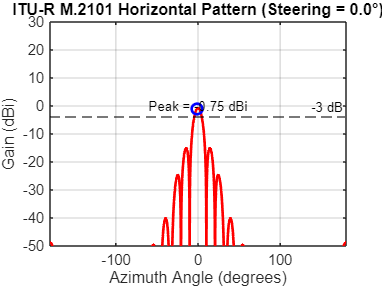


--------------------------------------
Horizontal Pattern
Peak Gain        : -0.75 dBi
3 dB Beamwidth   : 8.80 deg
Steering Azimuth : 0.00 deg
--------------------------------------


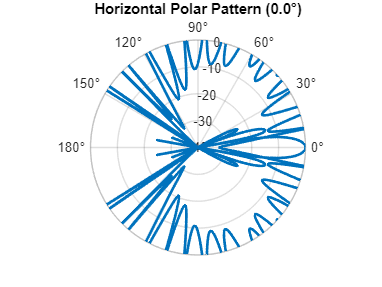

params.thetaScan = 45;
params.phiScan = 0;

horizontalCut(phi,params);

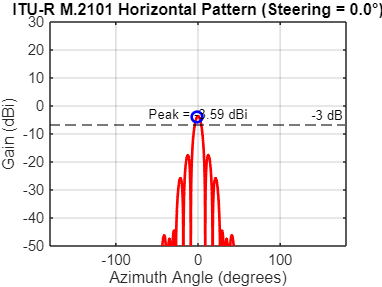


--------------------------------------
Horizontal Pattern
Peak Gain        : -3.59 dBi
3 dB Beamwidth   : 7.60 deg
Steering Azimuth : 0.00 deg
--------------------------------------


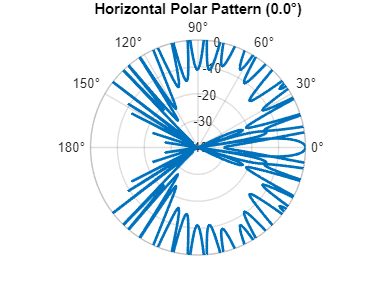

params.thetaScan = 55;
params.phiScan = 0;

horizontalCut(phi,params);